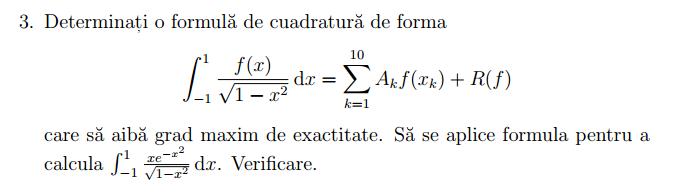

n = 10;
f = @(x) x .* exp(-x.^2);

% Nodes and weights for Chebyshev Type I
k = 1:n;
xk = cos((2*k - 1) * pi / (2*n))';
Ak = pi / n * ones(n, 1);  % All weights equal

% Apply the quadrature rule
I_approx = sum(Ak .* f(xk))

I_approx = 8.3267e-17

% Compute reference value using MATLAB's integral with weight
f_weighted = @(x) f(x) ./ sqrt(1 - x.^2);
I_exact = integral(f_weighted, -1, 1, 'AbsTol', 1e-12)

I_exact = -2.7756e-17

% Display error
fprintf('Approximate value: %.10f\n', I_approx);

Approximate value: 0.0000000000


fprintf('Exact value:       %.10f\n', I_exact);

Exact value:       -0.0000000000


fprintf('Absolute error:    %.2e\n', abs(I_approx - I_exact));

Absolute error:    1.11e-16
